# demographics of jellyfish by hosts

## load data

global DEFAULT_MATFILE_DIR
load([ DEFAULT_MATFILE_DIR '\jf_statsByHosts_CJF.mat']);

cmap=brewermap(256,'YlOrRd');
cmap(1,:)=[1 1 1];
cmap2=(viridis(256));
cmap2(1,:)=[1 1 1];

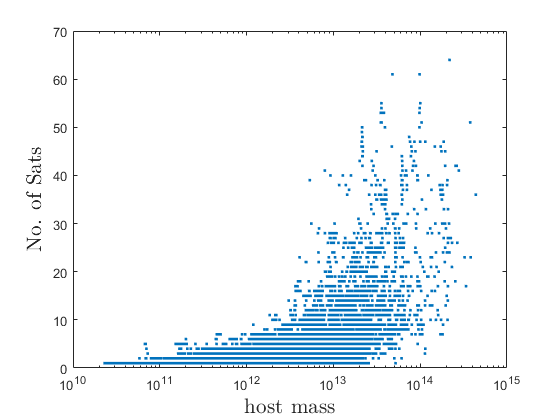

figure
semilogx(jfStats.M200c,jfStats.sampleSats,'.');
xlabelmine('host mass');
ylabelmine('No. of Sats');

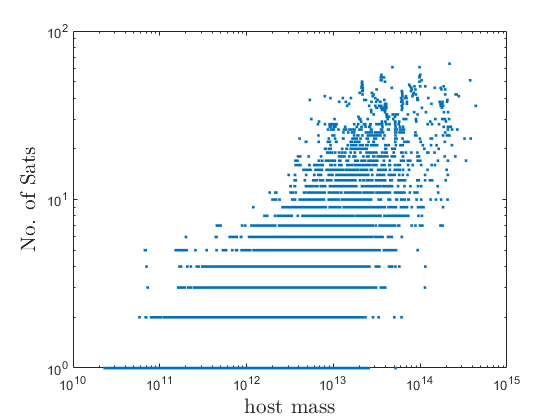


figure
loglog(jfStats.M200c,jfStats.sampleSats,'.');
xlabelmine('host mass');
ylabelmine('No. of Sats');

[bird, binsize, xl,yl]= histogram2d(log10(jfStats.M200c),jfStats.sampleSats,ones(size(jfStats.sampleSats)),...
    'xlim',[10 15],'ylim',[0 65],'len',65);
mm=jfStats.sim=="TNG100";
[bird100, ~, ~,~]= histogram2d(log10(jfStats.M200c(mm)),jfStats.sampleSats(mm),ones(size(jfStats.sampleSats(mm))),...
    'xlim',[10 15],'ylim',[0 65],'len',65);
[bird50, ~, ~,~]= histogram2d(log10(jfStats.M200c(~mm)),jfStats.sampleSats(~mm),ones(size(jfStats.sampleSats(~mm))),...
    'xlim',[10 15],'ylim',[0 65],'len',65);

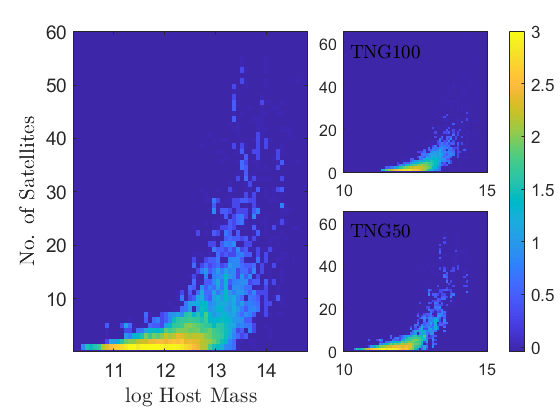


figure
t=tiledlayout(6,5);

nexttile([6 3])
imagesc(xl,yl,log10(squeeze(bird(:,:,1))))
set(gca,'ydir','normal','fontsize',14)
xlabelmine('log Host Mass');
ylabelmine('No. of Satellites');
colormap(cmap2)
caxis(log10([0.9 1000]))
cbh=colorbar;


nexttile([3 2])
imagesc(xl,yl,log10(squeeze(bird100(:,:,1))))
set(gca,'ydir','normal','fontsize',12)
text(10.2,55,'TNG100','Fontsize',14,'interpreter','latex')
colormap(cmap2)
caxis(log10([0.9 1000]))
%titlemine('TNG100',12);

nexttile([3 2])
imagesc(xl,yl,log10(squeeze(bird50(:,:,1))))
set(gca,'ydir','normal','fontsize',12)
text(10.2,55,'TNG50','Fontsize',14,'interpreter','latex')
colormap(cmap2)
caxis(log10([0.9 1000]))



%colorbar
%titlemine('All');

%figure

%titlemine('TNG100',12);

colormap(cmap2)
caxis(log10([0.9 1000]))
%colorbar

%figure


%titlemine('TNG50',12);
cbh.Layout.Tile = 'east';

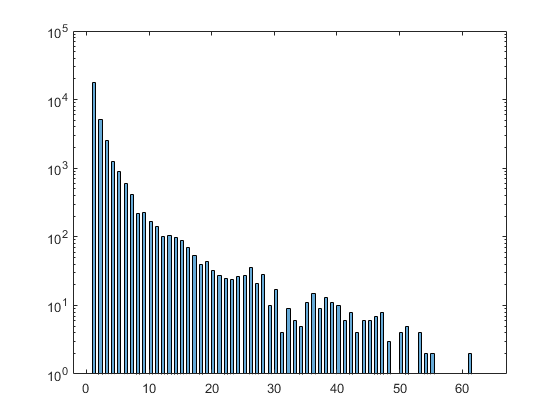




figure
histogram(jfStats.sampleSats)
set(gca,'YScale','log')

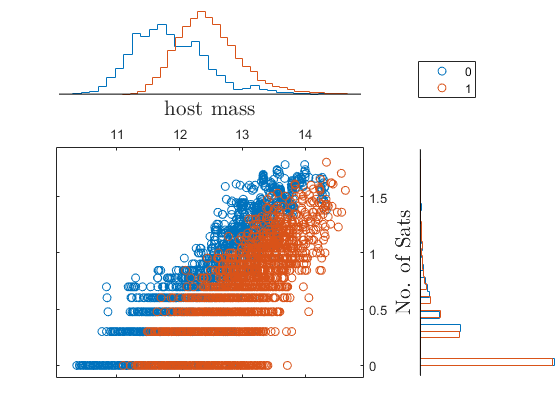


figure
scatterhist(log10(jfStats.M200c),log10(jfStats.sampleSats),...
    'group',jfStats.sim=="TNG100",...
    'location','northeast','Direction','out','kernel','off',...
    'nbins',30);
xlabelmine('host mass');
ylabelmine('No. of Sats');

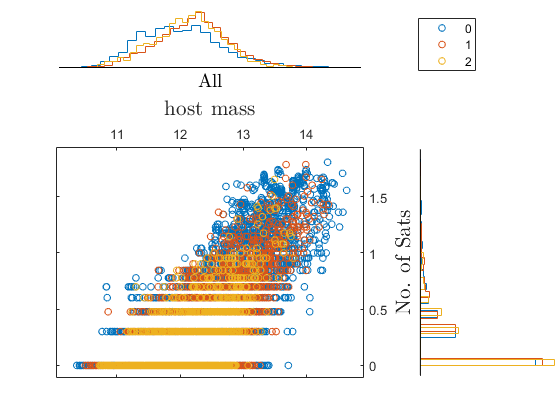

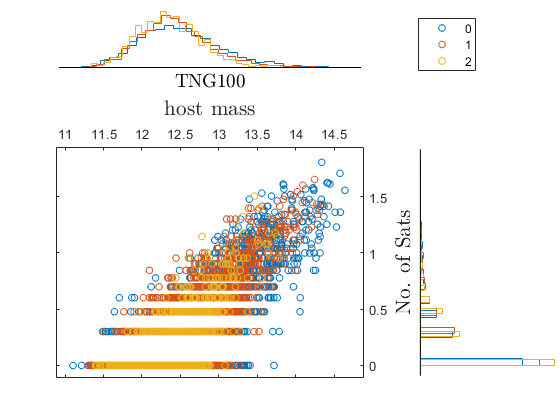

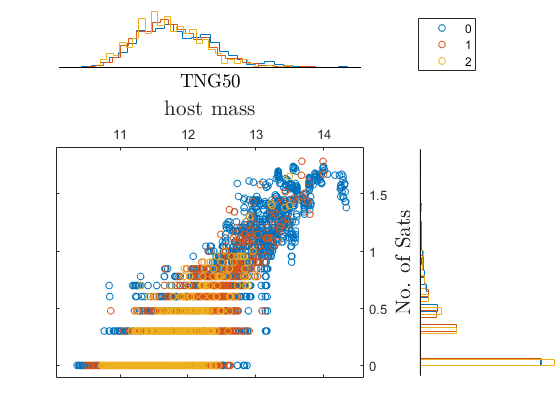

zr=illustris.utils.snap2redshift(jfStats.snap);
gr=ones(size(zr));
gr(zr<=0.5)=0;
gr(zr>0.5 & zr<=1)=1;
gr(zr>1 & zr<=2)=2;

for j=1:3
    switch j
        case 1
            msk=true(size(jfStats.sim));
            tit='All';
        case 2
            msk=jfStats.sim=="TNG100";
            tit='TNG100';
        case 3
            msk=jfStats.sim=="TNG50";
            tit='TNG50';
            
    end
    
    figure
    scatterhist(log10(jfStats.M200c(msk)),log10(jfStats.sampleSats(msk)),...
        'group',gr(msk),...
        'location','northeast','Direction','out','kernel','off',...
        'nbins',30,'markersize',5);
    xlabelmine('host mass');
    ylabelmine('No. of Sats');
    titlemine(tit);
end

## plot jf fractions

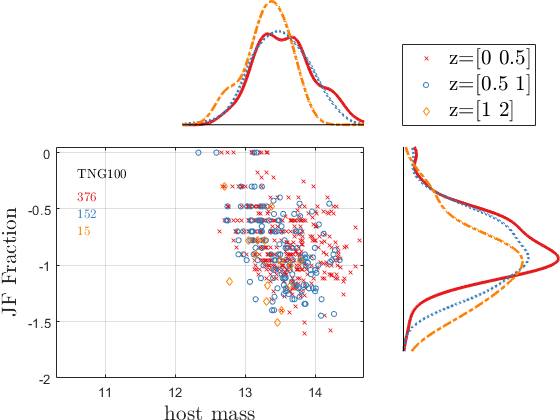

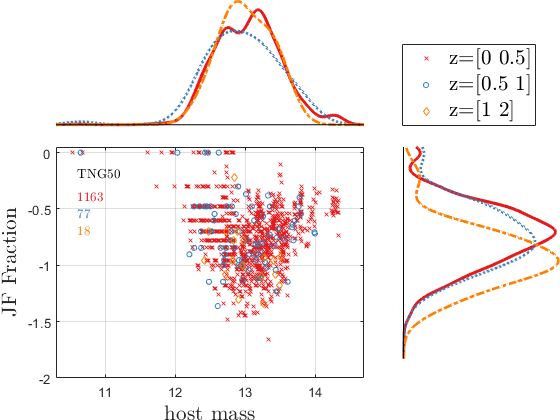

zr=illustris.utils.snap2redshift(jfStats.snap);
gr=ones(size(zr));
gr(zr<=0.5)=0;
gr(zr>0.5 & zr<=1)=1;
gr(zr>1 & zr<=2.1)=2;
% grr=string(gr);
% grr(zr<=0.5)="$z\leq 0.5$";
% grr(zr>0.5 & zr<=1)="$z>0.5 \& z\leq 1$";
% grr(zr>1 & zr<=2.1)="$z>1 \& z\leq 2$";

jff=jfStats.JFNum./jfStats.sampleSats;
mmm=jff==0;

% msk=~mmm;
% tab=table(jfStats.M200c(msk),jff(msk),grr(msk),'VariableNames',{"host mass","JF Fraction","redshift"});
%
%  msk=jfStats.sim=="TNG100" & ~mmm;
% tab100=table(jfStats.M200c(msk),jff(msk),grr(msk),'VariableNames',{'host mass','JF Fraction','redshift'});
%
% msk=jfStats.sim=="TNG50" & ~mmm ;
% tab50=table(jfStats.M200c(msk),jff(msk),grr(msk),'VariableNames',{'host mass','JF Fraction','redshift'});



% give fictitios frac for zero
% base=1e-2;
% scat=0.2;
% mmm=jff==0;
% jff(mmm)=base.*10.^(scat.*rand(1,sum(mmm)));

cmap=brewermap(5,'Set1');
for j=2:3
    switch j
        case 1
            msk=true(size(jfStats.sim)) ;
            % tabl=tab;
            tit='All';
        case 2
            %tabl=tab100;
            msk=jfStats.sim=="TNG100"  ;
            tit='TNG100';
        case 3
            %tabl=tab50;
            msk=jfStats.sim=="TNG50"  ;
            tit='TNG50';
            
    end
    
    mskk=msk & ~mmm;
    %
    % hf=figure;
    % scatterhistogram(tabl,'host mass','JF Fraction')
    
    
    
    mm0=mskk & gr==0;
    mm1=mskk & gr==1;
    mm2=mskk & gr==2;
    
    
    hf=figure;
%     scatterhist((jfStats.M200c(mskk)),(jff(mskk)),...
%         'group',gr(mskk),...
%         'location','northeast','Direction','out','kernel','off',...
%         'nbins',50,'markersize',4,'marker','x+d');
%     set(gca,'yscale','log','xscale','log','xaxislocation','bottom',...
%         'yaxislocation','left')
 scatterhist(log10(jfStats.M200c(mskk)),log10(jff(mskk)),...
        'group',gr(mskk),...
        'location','northeast','Direction','out','kernel','on',...
        'nbins',50,'markersize',4,'marker','xod','color',cmap([1 2 5],:));
    set(gca,'xaxislocation','bottom',...
        'yaxislocation','left')
    colormap(cmap)
    %hf.Children(2).XScale='log';
    %hf.Children(3).XScale='log';
    hf.Children(4).String = {'z=[0 0.5]','z=[0.5 1]','z=[1 2]'};  %{"$z\leq 0.5$","$z>0.5 \& z\leq 1$","$z>1 \& z\leq 2$"};
    
    
    %
    hf.Children(4).Interpreter ='latex';
    hf.Children(4).FontSize =16 ;
    
    grid
    % hold on
    % plot(log10(jfStats.M200c(msk & mmm)),log10(jff(msk & mmm)),'.')
    text(10.6,-0.2,tit,'Interpreter','latex');
    text(10.6,-0.4,num2str(sum(mm0)),'Interpreter','latex','Color',cmap(1,:));
    text(10.6,-0.55,num2str(sum(mm1)),'Interpreter','latex','Color',cmap(2,:));
    text(10.6,-0.7,num2str(sum(mm2)),'Interpreter','latex','Color',cmap(5,:));
    xlim([10.3 14.7])
    ylim([-2 0.05])
    xlabelmine('host mass');
    ylabelmine('JF Fraction');
    %titlemine(tit);
end

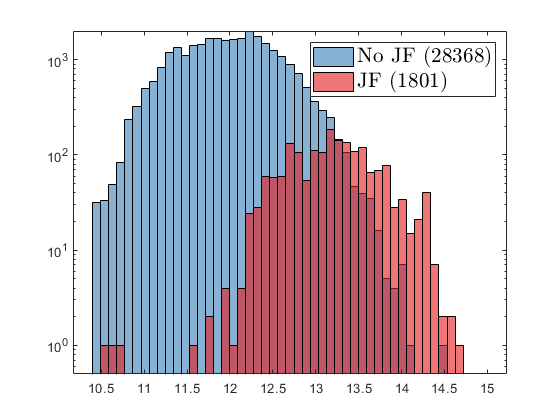


figure
histogram(log10(jfStats.M200c(mmm)),linspace(10.4,15,50),'facecolor',cmap(2,:));
hold on;
histogram(log10(jfStats.M200c(~mmm)),linspace(10.4,15,50),'facecolor',cmap(1,:));
%text(10^14.2,1000,num2str(sum(mmm)),'Interpreter','latex','Color',cmap(2,:));
%text(10^14.2,700,num2str(sum(~mmm)),'Interpreter','latex','Color',cmap(1,:));
legend({['No JF (' num2str(sum(mmm)) ')'], ['JF (' num2str(sum(~mmm)) ')'] },'Interpreter','latex','fontsize',16    )
set(gca,'yscale','log')
ylim([0.5 2000 ])